clear
clc
close all

syms Ki Kp Kd s Gc1 Gc2 a b
K = 2;
A = s+1;
B = s^3+8*s^2+15*s;
Psym = K*A/B

$$Psym = \frac{2\,s+2}{s^{3}+8\,s^{2}+15\,s}$$

Csym = (Kp*s + Ki + Kd*s^2)/s % 1/(A)

$$Csym = \frac{\mathrm{Kd}\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}{s}$$

GYDsym = s*A/(s*B + (Kp*s + Ki + Kd*s^2)*K)

$$GYDsym = \frac{s\,\left(s+1\right)}{2\,\mathrm{Ki}+s\,\left(s^{3}+8\,s^{2}+15\,s\right)+2\,\mathrm{Kp}\,s+2\,\mathrm{Kd}\,s^{2}}$$

GYRsym = collect(Gc1*Psym/(1+Csym*Psym),s)

$$GYRsym = \frac{\left(2\,{\mathrm{Gc}}_{1}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1}\right)\,s}{s^{4}+\left(2\,\mathrm{Kd}+8\right)\,s^{3}+\left(2\,\mathrm{Kd}+2\,\mathrm{Kp}+15\right)\,s^{2}+\left(2\,\mathrm{Ki}+2\,\mathrm{Kp}\right)\,s+2\,\mathrm{Ki}}$$

[num,den] = numden(GYRsym)

$$num = 2\,{\mathrm{Gc}}_{1}\,s^{2}+2\,{\mathrm{Gc}}_{1}\,s$$

$$den = 2\,\mathrm{Ki}+2\,\mathrm{Ki}\,s+2\,\mathrm{Kp}\,s+2\,\mathrm{Kd}\,s^{2}+2\,\mathrm{Kd}\,s^{3}+2\,\mathrm{Kp}\,s^{2}+15\,s^{2}+8\,s^{3}+s^{4}$$

den = collect(den)

$$den = s^{4}+\left(2\,\mathrm{Kd}+8\right)\,s^{3}+\left(2\,\mathrm{Kd}+2\,\mathrm{Kp}+15\right)\,s^{2}+\left(2\,\mathrm{Ki}+2\,\mathrm{Kp}\right)\,s+2\,\mathrm{Ki}$$

coeffs_den = coeffs(den, s, 'All');
w = coeffs_den(end-2:end);
w = sum(w.*s.^[2 1 0])

$$w = \left(2\,\mathrm{Kd}+2\,\mathrm{Kp}+15\right)\,s^{2}+\left(2\,\mathrm{Ki}+2\,\mathrm{Kp}\right)\,s+2\,\mathrm{Ki}$$

Gc1 = w/(K*A*s)

$$Gc1 = \frac{\left(2\,\mathrm{Kd}+2\,\mathrm{Kp}+15\right)\,s^{2}+\left(2\,\mathrm{Ki}+2\,\mathrm{Kp}\right)\,s+2\,\mathrm{Ki}}{s\,\left(2\,s+2\right)}$$

Gc2 = simplify(Csym-Gc1)

$$Gc2 = \frac{s\,\left(2\,\mathrm{Kd}\,s-15\right)}{2\,\left(s+1\right)}$$

Encontrar los coeficientes

z = 0.8;
%ts = 1;
%wn = 4/(z*ts)
wn = 25;
b = 3;
poli_2do_orden1 = s^2 + 2*z*wn*s + wn^2;
poli_2do_orden2 = s^2 + a*s + b;
polinomio_deseado = poli_2do_orden1*poli_2do_orden2;
coeffs_deseado = coeffs(expand(polinomio_deseado), s, 'All')

$$coeffs\_deseado = \left(\begin{array}{ccccc} 1 & a+40 & 40\,a+628 & 625\,a+120 & 1875 \end{array}\right)$$

Resolución de sistema de ecuaciones

eqs = [coeffs_den(2:5)] == [coeffs_deseado(2:5)]

$$eqs = \left(\begin{array}{cccc} 2\,\mathrm{Kd}+8=a+40 & 2\,\mathrm{Kd}+2\,\mathrm{Kp}+15=40\,a+628 & 2\,\mathrm{Ki}+2\,\mathrm{Kp}=625\,a+120 & 2\,\mathrm{Ki}=1875 \end{array}\right)$$

S = solve(eqs, [Ki, Kp, Kd, a]);
Ki = double(S.Ki(1))

Ki = 937.5000

Kp = double(S.Kp(1))

Kp = 368.2338

Kd = double(S.Kd(1))

Kd = 17.9932

a = double(S.a(1))

a = 3.9863

%b = double(S.b(1))

Numéricamente

numPlanta =[1 1];
K = 2;
denPlanta = [1 8 15 0];
P = tf(K*numPlanta, denPlanta)

P =
 
       2 s + 2
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.



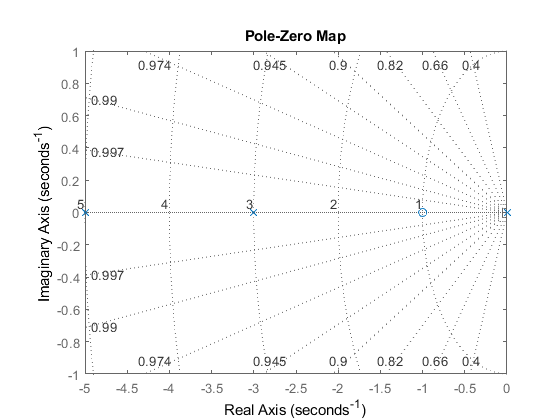

pzmap(P)
grid on

C = tf([Kd Kp Ki], [1,0])

C =
 
  17.99 s^2 + 368.2 s + 937.5
  ---------------------------
               s
 
Continuous-time transfer function.



% [numGc2,denGc2] = numden(Gc2);
% numGc2 = sym2poly(numGc2);
% denGc2 = sym2poly(denGc2);
Gc2 = tf([K*Kd -15 0],K*[numPlanta])

Gc2 =
 
  35.99 s^2 - 15 s
  ----------------
      2 s + 2
 
Continuous-time transfer function.



Gc1 = C - Gc2

Gc1 =
 
  787.5 s^2 + 2611 s + 1875
  -------------------------
         2 s^2 + 2 s
 
Continuous-time transfer function.



GYD = feedback(P,C)

GYD =
 
                  2 s^2 + 2 s
  -------------------------------------------
  s^4 + 43.99 s^3 + 787.5 s^2 + 2611 s + 1875
 
Continuous-time transfer function.



GYR = GYD * Gc1

GYR =
 
            1575 s^4 + 6798 s^3 + 8973 s^2 + 3750 s
  -----------------------------------------------------------
  2 s^6 + 89.97 s^5 + 1663 s^4 + 6798 s^3 + 8973 s^2 + 3750 s
 
Continuous-time transfer function.



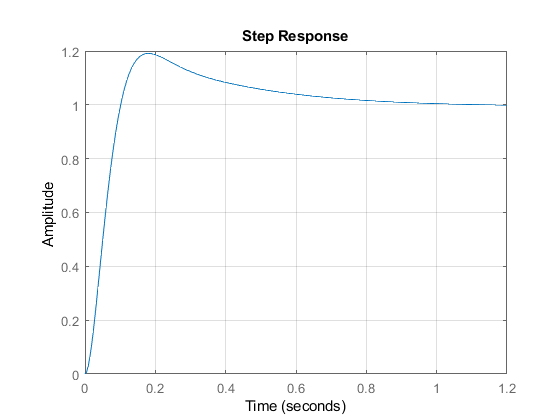

step(GYR)
grid on

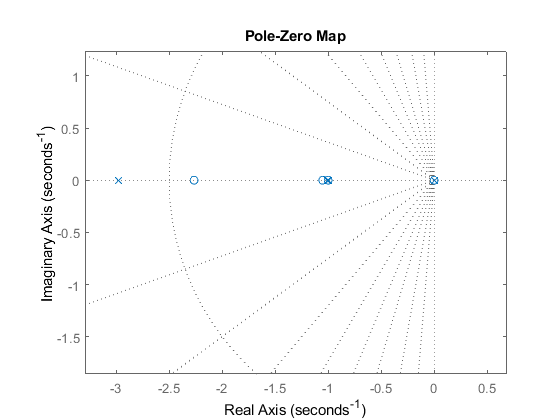

pzmap(GYR)
grid on

stepinfo(GYR)

ans = struct with fields:
        RiseTime: 0.0697
    SettlingTime: 0.7569
     SettlingMin: 0.9353
     SettlingMax: 1.1911
       Overshoot: 19.1114
      Undershoot: 0
            Peak: 1.1911
        PeakTime: 0.1796


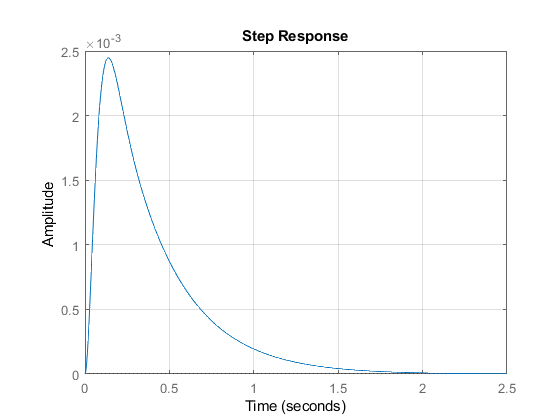

step(GYD)
grid on

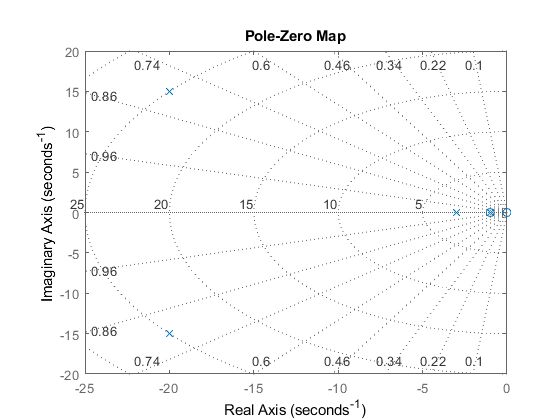

pzmap(GYD)
grid on

stepinfo(GYD)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 1.4509
     SettlingMin: 5.6826e-07
     SettlingMax: 0.0024
       Overshoot: Inf
      Undershoot: 0
            Peak: 0.0024
        PeakTime: 0.1382


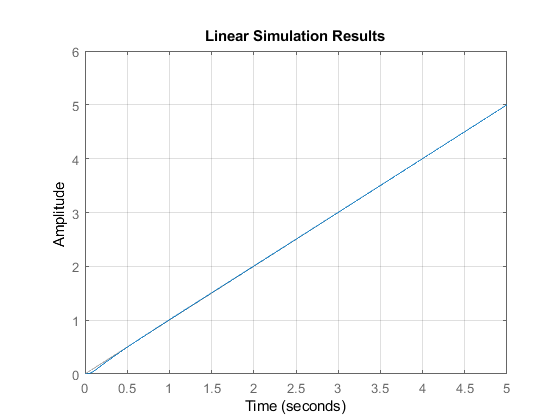

vt = 0:0.01:5;
u = vt;
lsim(GYR,u,vt)
grid on

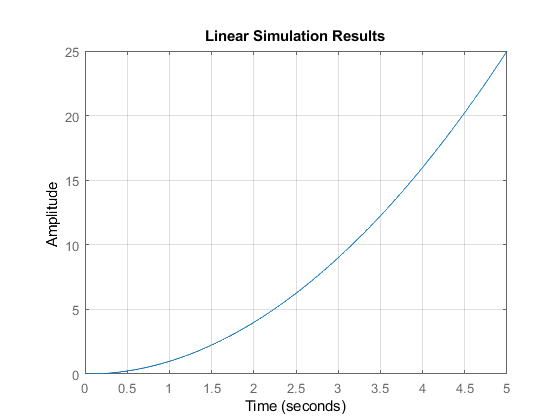

u = vt.^2;
lsim(GYR,u,vt)
grid on